# Estimate Doppler and Range with Specified PRF

Estimate the Doppler and range responses for three targets. Two targets are approximately 2000 m away, while the third is approximately 3500 m away. In addition, two of the targets are stationary relative to the radar. The third is moving away from the radar at about 100 m/s. Specify the pulse repetition frequency.

Load data for a pulsed radar signal. 

load RangeDopplerExampleData;

Create a range-Doppler response object. Set the PRF to 25 kHz.

response = phased.RangeDopplerResponse('DopplerFFTLengthSource','Property', ...
   'DopplerFFTLength',RangeDopplerEx_MF_NFFTDOP,'SampleRate', ...
   RangeDopplerEx_MF_Fs,'DopplerOutput','Speed','OperatingFrequency', ...
   RangeDopplerEx_MF_Fc,'PRFSource','Property','PRF',25.0e3);

Calculate the range-Doppler response.

[resp,rng_grid,dop_grid] = response(RangeDopplerEx_MF_X, ...
    RangeDopplerEx_MF_Coeff);

Plot the range-Doppler response.

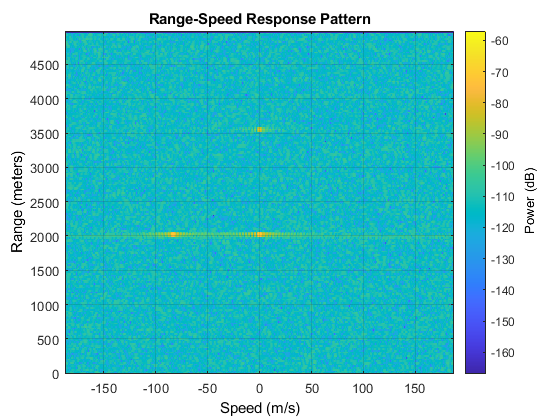

plotResponse(response,RangeDopplerEx_MF_X,RangeDopplerEx_MF_Coeff,'Unit','db')

*Copyright 2012 The MathWorks, Inc.*

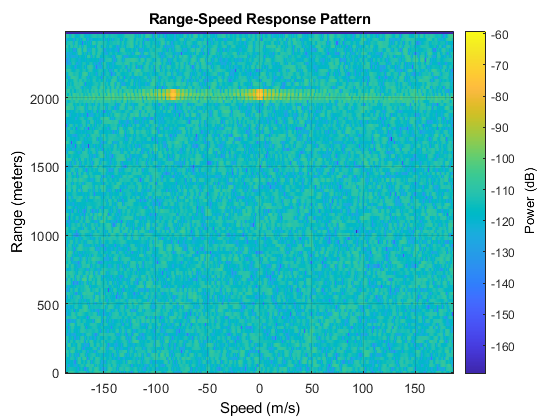

modData = RangeDopplerEx_MF_X(1:100,1:100)
plotResponse(response,modData,RangeDopplerEx_MF_Coeff,'Unit','db')